# Title

## Setup

alpha = 1/5;
d = 0.235; % m

U_RANGE = [0 3.2];
T_RANGE = U_RANGE ./ alpha;
N = 100;

us = linspace(U_RANGE(1), U_RANGE(2), N)';
ts = us ./ alpha;

equations;

## Load Encoder Data

clf; load("encoder_data.mat");

enc_dt = diff(enc_t);
enc_dl = diff(enc_l) ./ enc_dt;
enc_dr = diff(enc_r) ./ enc_dt;


## Exercise 21.1

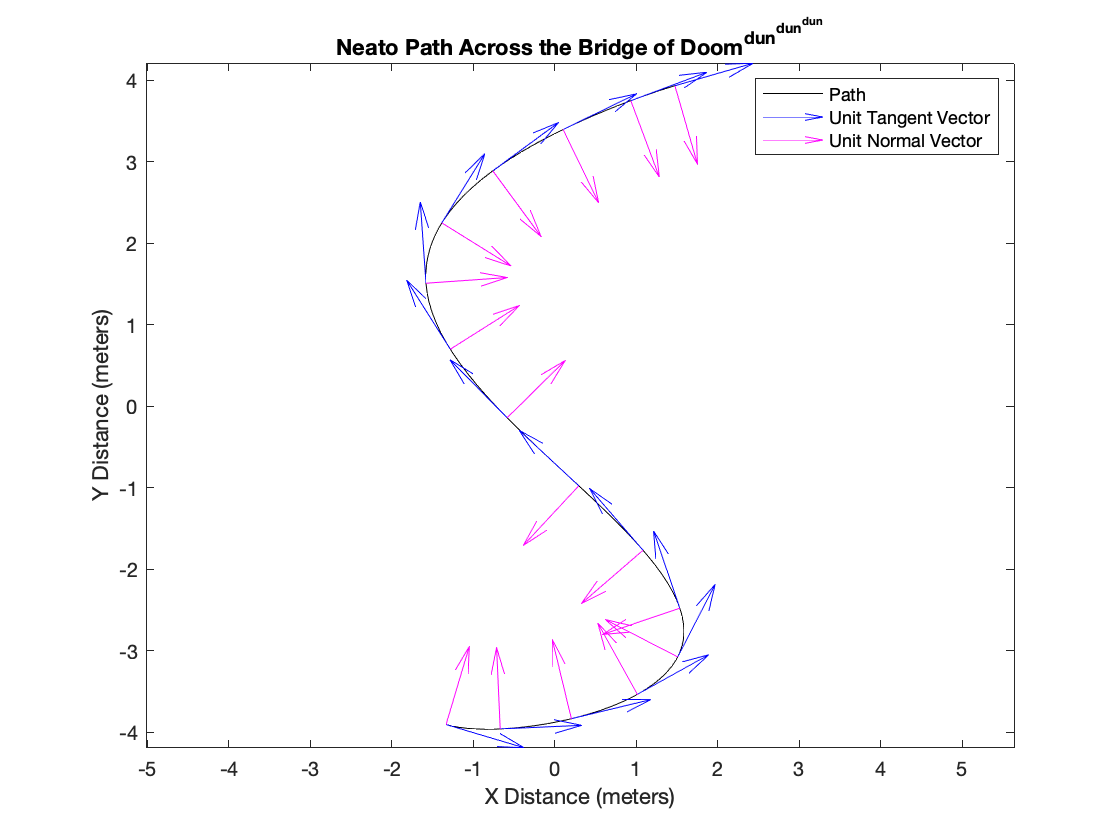

figure(1); clf;


points = double(subs(r, t, ts));
plot(points(:, 1), points(:, 2), 'k-'); axis equal; hold on;

% This is hacky, but a reliable way to ensure these aren't shadowed before
% we get to the bottom.
calculated_ts = ts;
calculated_path = points;

ts_for_arrows = linspace(T_RANGE(1), T_RANGE(2), N / 6)';
start_points_for_calc_arrows = double(subs(r, t, ts_for_arrows));
calc_that_end_points = double(subs(T_hat, t, ts_for_arrows));
calc_nhat_end_points = double(subs(N_hat, t, ts_for_arrows));
quiver(start_points_for_calc_arrows(:, 1), start_points_for_calc_arrows(:, 2), calc_that_end_points(:, 1), calc_that_end_points(:, 2), "off", 'filled', 'b');
quiver(start_points_for_calc_arrows(:, 1), start_points_for_calc_arrows(:, 2), calc_nhat_end_points(:, 1), calc_nhat_end_points(:, 2), "off", "filled", 'm');
legend("Path", "Unit Tangent Vector", "Unit Normal Vector")
xlabel("X Distance (meters)");
ylabel("Y Distance (meters)");
title("Neato Path Across the Bridge of Doom^{dun^{dun^{dun}}}")

## Exercise 21.2

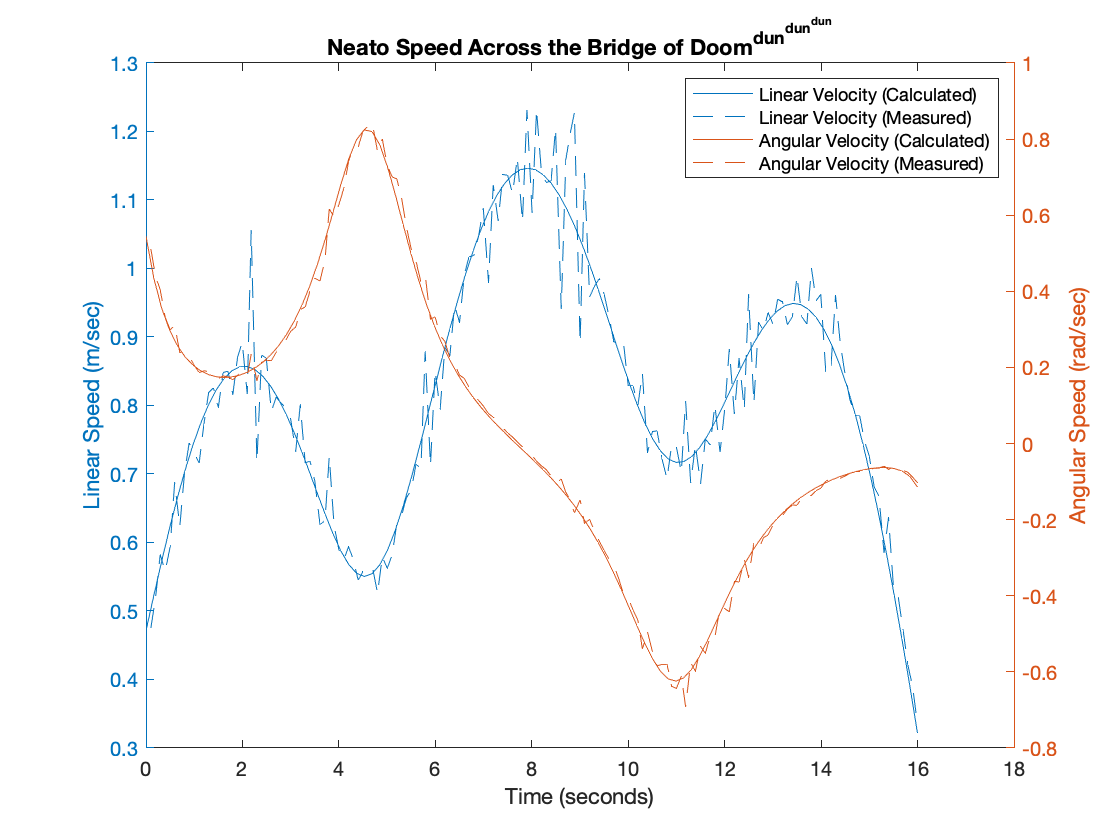

speeds = double(subs(speed, t, ts));
rot_speeds = double(subs(rotation_speed, t, ts));

%% Figure out the measured values
% These are exposed for when we know vl or vr and need to solve for
% something else.
syms vl vr vlin vrot;
assume(vl, 'real');
assume(vr, 'real');
assume(vlin, 'real');
assume(vrot, 'real');

vl_eqn = vl == vlin - (vrot .* (d ./ 2));
vr_eqn = vr == vlin + (vrot .* (d ./ 2));

[vrot, vlin] = solve([vl_eqn, vr_eqn], [vrot, vlin]);
vl = enc_dl;
vr = enc_dr;

vrots = double(subs(vrot));
vlins = double(subs(vlin));

figure(2); clf;
yyaxis left;
plot(ts, speeds, '-'); hold on;
plot(enc_t(2:end), vlins, '--'); hold off;
ylabel("Linear Speed (m/sec)");
yyaxis right;
plot(ts, rot_speeds, '-'); hold on;
plot(enc_t(2:end), vrots, '--'); hold off;
%legend("Linear Speed", "Angular Speed")
xlabel("Time (seconds)");
ylabel("Angular Speed (rad/sec)");
title("Neato Speed Across the Bridge of Doom^{dun^{dun^{dun}}}");
legend("Linear Velocity (Calculated)", "Linear Velocity (Measured)", "Angular Velocity (Calculated)", "Angular Velocity (Measured)")

## Exercise 21.3

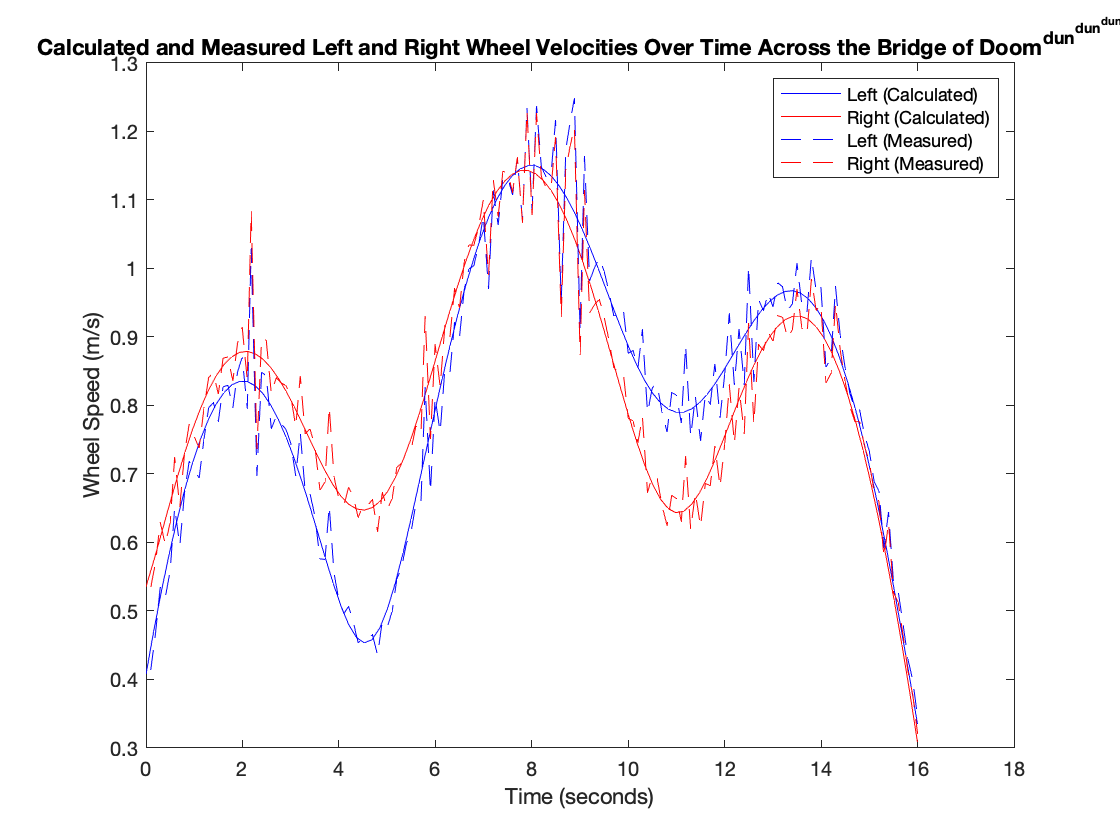

figure(3); clf;
v_ls = double(subs(v_l, t, ts));
v_rs = double(subs(v_r, t, ts));
plot(ts, v_ls, 'b-'); hold on;
plot(ts, v_rs, 'r-');
plot(enc_t(2:end), enc_dl, 'b--');
plot(enc_t(2:end), enc_dr, 'r--');

title("Calculated and Measured Left and Right Wheel Velocities Over Time Across the Bridge of Doom^{dun^{dun^{dun}}}")
xlabel("Time (seconds)");
ylabel("Wheel Speed (m/s)");
legend("Left (Calculated)", "Right (Calculated)", "Left (Measured)", "Right (Measured)");

## Calculate Odomotry

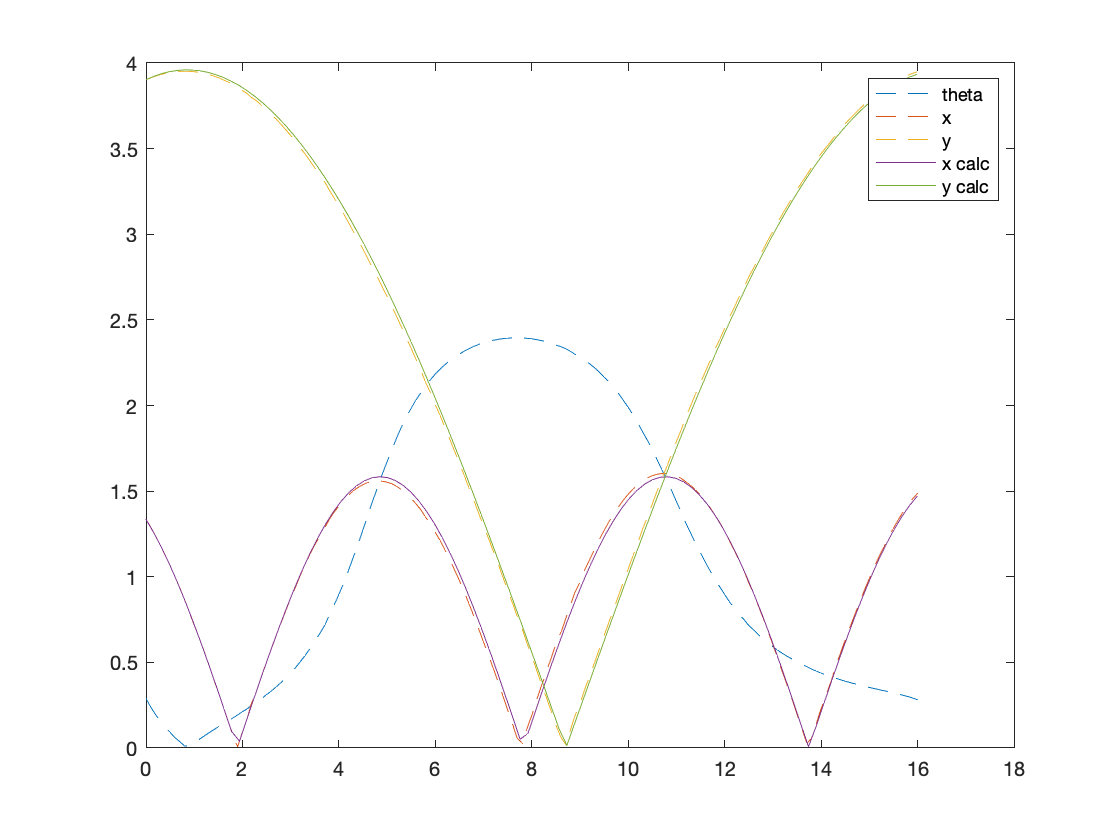

% syms omega(t) theta(t) v(t) r_x(t) r_y(t) t
% 
% dtheta = omega;
% theta = int(dtheta)
% dr_x = v * cos(theta);
% r_x =  simplify(int(dr_x, t))
% dr_y = v * sin(theta)
% r_y = int(dr_y, t)
% omega = vrots;
% v = vlins;
% % t = enc_t(2:end)
% calc_rx = matlabFunction(subs(r_x))
% calc_ry = matlabFunction(subs(r_y))
% rxs = calc_rx(enc_t(2:end))
% rys = calc_ry(enc_t(2:end))

% omegas = vrots;
% vs = vlins; 
% dt = enc_dt;
% 
% thetas = mod(cumsum(omegas) ./ cumsum(dt), 2 * pi);
% rxs = cumsum(vs .* cos(thetas) ./ cumsum(dt));
% rys = cumsum(vs .* sin(thetas) ./ cumsum(dt));
% figure(5); clf;
% plot(enc_t(2:end), thetas, '--'); hold on;
% plot(enc_t(2:end), rxs, '--');
% plot(enc_t(2:end), rys, '--');
% plot(hacky_ts, hacky_points(:, 1), '-');
% plot(hacky_ts, hacky_points(:, 2), '-');
% legend("theta", "x", "y", "x calc", "y calc")

thetas = zeros(length(enc_t), 1);
rxs = zeros(length(enc_t), 1);
rys = zeros(length(enc_t), 1);

that_0 = double(subs(T_hat, T_RANGE(1)));
thetas(1) = atan(that_0(2)/that_0(1));
rxs(1) = calculated_path(1, 1);
rys(1) = calculated_path(1, 2);

for i=1:length(enc_dt)
    thetas(i + 1) = thetas(i) + (vrots(i) * enc_dt(i));
    rxs(i + 1) = rxs(i) + (vlins(i) * cos(thetas(i + 1)) * enc_dt(i));
    rys(i + 1) = rys(i) + (vlins(i) * sin(thetas(i + 1)) * enc_dt(i));
end

Thats = [cos(thetas), sin(thetas)];
Nhats = [-cos(thetas), -sin(thetas)];


figure(5); clf;
plot(enc_t(1:end), abs(thetas), '--'); hold on;
plot(enc_t(1:end), abs(rxs), '--');
plot(enc_t(1:end), abs(rys), '--');
plot(calculated_ts, abs(calculated_path(:, 1)), '-');
plot(calculated_ts, abs(calculated_path(:, 2)), '-');
legend("theta", "x", "y", "x calc", "y calc")

## Measured Paths

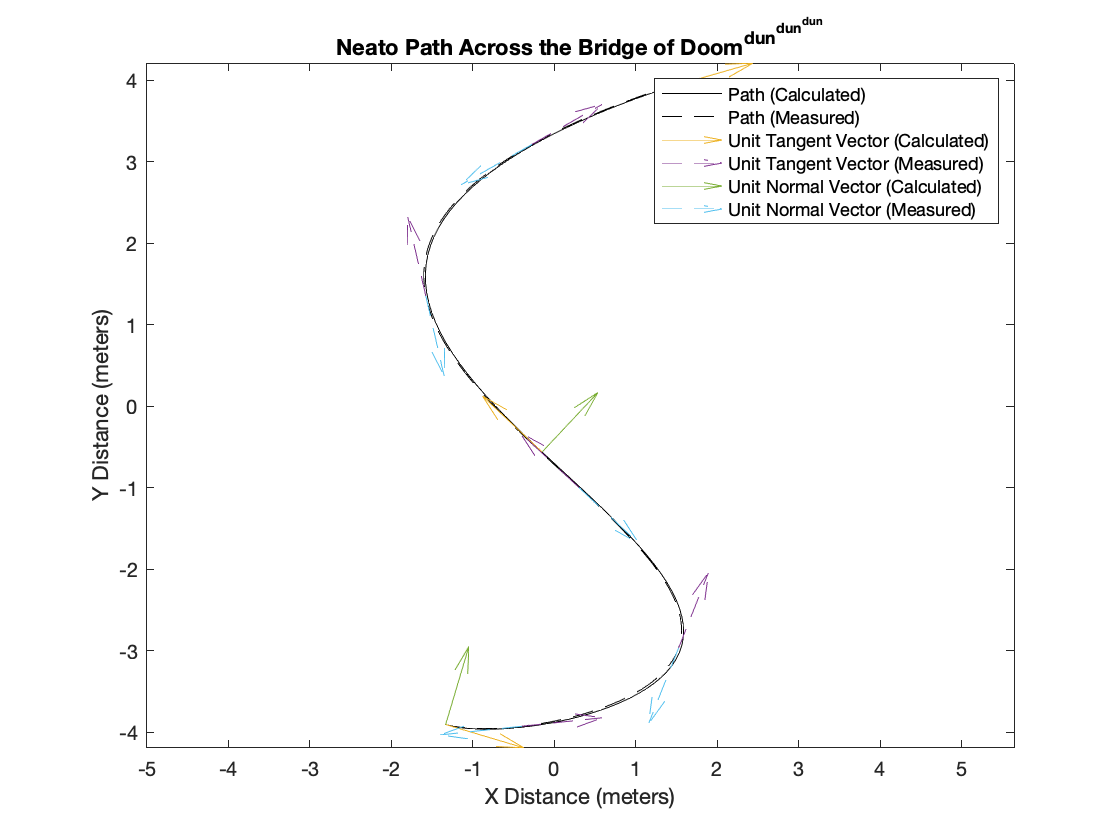

figure(4); clf;

plot(calculated_path(:, 1), calculated_path(:, 2), 'k-'); axis equal; hold on;
plot(rxs, rys, 'k--'); 

vector_spacing = 30;

ts_for_arrows = linspace(T_RANGE(1), T_RANGE(2), N / vector_spacing)';
start_points_for_calc_arrows = double(subs(r, t, ts_for_arrows));
calc_that_end_points = double(subs(T_hat, t, ts_for_arrows));
calc_nhat_end_points = double(subs(N_hat, t, ts_for_arrows));
quiver(start_points_for_calc_arrows(:, 1), start_points_for_calc_arrows(:, 2), calc_that_end_points(:, 1), calc_that_end_points(:, 2), "off", 'filled', '-');
quiver(rxs(round(vector_spacing / 2):vector_spacing:end), rys(round(vector_spacing / 2):vector_spacing:end), Thats(round(vector_spacing / 2):vector_spacing:end, 1), Thats(round(vector_spacing / 2):vector_spacing:end, 2), "off", 'filled', '--');
quiver(start_points_for_calc_arrows(:, 1), start_points_for_calc_arrows(:, 2), calc_nhat_end_points(:, 1), calc_nhat_end_points(:, 2), "off", "filled", '-');
quiver(rxs(round(vector_spacing / 2):vector_spacing:end), rys(round(vector_spacing / 2):vector_spacing:end), Nhats(round(vector_spacing / 2):vector_spacing:end, 1), Nhats(round(vector_spacing / 2):vector_spacing:end, 2), "off", "filled", '--');
legend("Path (Calculated)", "Path (Measured)", "Unit Tangent Vector (Calculated)",  "Unit Tangent Vector (Measured)", "Unit Normal Vector (Calculated)", "Unit Normal Vector (Measured)")
xlabel("X Distance (meters)");
ylabel("Y Distance (meters)"); 
title("Neato Path Across the Bridge of Doom^{dun^{dun^{dun}}}")